paramNameValStruct.SimulationMode = 'normal';
paramNameValStruct.TimeOut        = 50;
simOut = sim('DoubleMotor_CSVposRef',paramNameValStruct);
simOut.getSimulationMetadata.TimingInfo

ans = struct with fields:
          WallClockTimestampStart: '2022-01-19 15:30:46'
           WallClockTimestampStop: '2022-01-19 15:31:30'
    InitializationElapsedWallTime: 0.6355
         ExecutionElapsedWallTime: 41.9288
       TerminationElapsedWallTime: 1.2271
             TotalElapsedWallTime: 43.7914
                     ProfilerData: 'Profiler is not enabled'


t_f = 10; % end time
opts = delimitedTextImportOptions("NumVariables",4, ...
    "Delimiter",',', ...
    "VariableNames",{'Left hip','Left knee','Right hip','Right knee'}, ...
    "VariableTypes",{'double','double','double','double'}, ...
    "PreserveVariableNames",true);
tabularData = readtable('Data\Gait\Gait_2Joints_02.csv',opts);
sm_t = linspace(0,t_f,size(tabularData,1));
sm_traj = deg2rad(table2array(tabularData));
sm_path = timeseries(sm_traj,sm_t);

p1 = simOut.p1;
Ts = simOut.tout(2);
% create iddata type with inputs and outputs
data1 = iddata(p1.Data(:,2),p1.Data(:,1),Ts,'Name','Motor 1 response', ...
    'InputName',{'Time'},'InputUnit',{'s'}, ...
    'OutputName',{'Position'},'OutputUnit',{'rad'});
% transfer function estimation with 2 poles and no zero
m11 = tfest(data1,2,0); m11.Report.Fit

ans = struct with fields:
    FitPercent: 99.1171
       LossFcn: 361.0124
           MSE: 361.0124
           FPE: 362.8211
           AIC: 1.7472e+04
          AICc: 1.7472e+04
          nAIC: 5.8939
           BIC: 1.7500e+04


% transfer function estimation with 1 pole and no zero
m12 = tfest(data1,1,0); m12.Report.Fit

ans = struct with fields:
    FitPercent: 99.1171
       LossFcn: 360.9908
           MSE: 360.9908
           FPE: 362.0749
           AIC: 1.7468e+04
          AICc: 1.7468e+04
          nAIC: 5.8919
           BIC: 1.7485e+04


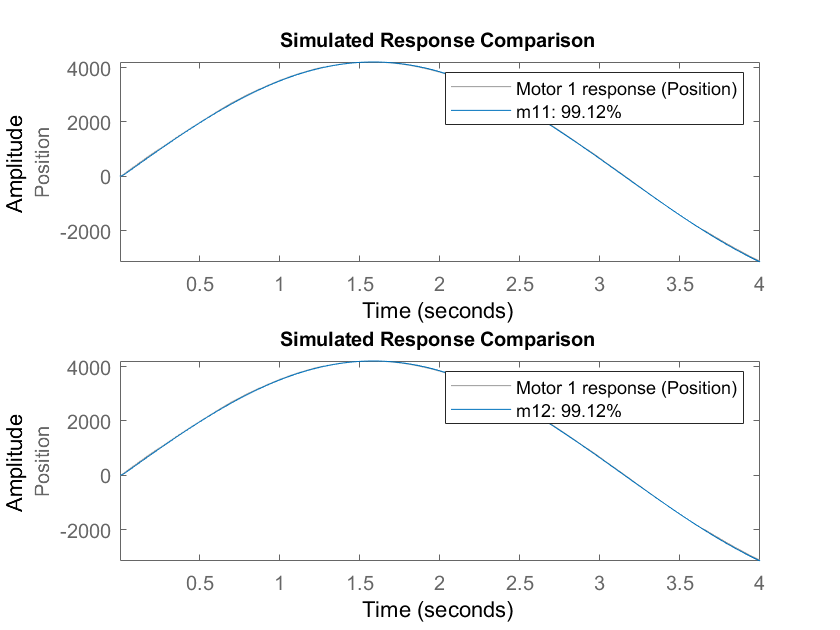

figure
subplot(2,1,1)
compare(data1,m11) % first order model evaluation
subplot(2,1,2)
compare(data1,m12) % second order model evaluation

p2 = simOut.p2;
data2 = iddata(p2.Data(:,2),p2.Data(:,1),Ts,'Name','Motor 2 response', ...
    'InputName',{'Time'},'InputUnit',{'s'}, ...
    'OutputName',{'Position'},'OutputUnit',{'rad'});
% transfer function estimation with 2 poles and no zero
m21 = tfest(data2,2,0); m21.Report.Fit

ans = struct with fields:
    FitPercent: 99.1272
       LossFcn: 353.1976
           MSE: 352.8787
           FPE: 354.6466
           AIC: 1.7427e+04
          AICc: 1.7427e+04
          nAIC: 5.8711
           BIC: 1.7455e+04


% transfer function estimation with 1 pole and no zero
m22 = tfest(data2,1,0); m22.Report.Fit

ans = struct with fields:
    FitPercent: 99.1272
       LossFcn: 352.8909
           MSE: 352.8909
           FPE: 353.9506
           AIC: 1.7423e+04
          AICc: 1.7423e+04
          nAIC: 5.8692
           BIC: 1.7440e+04


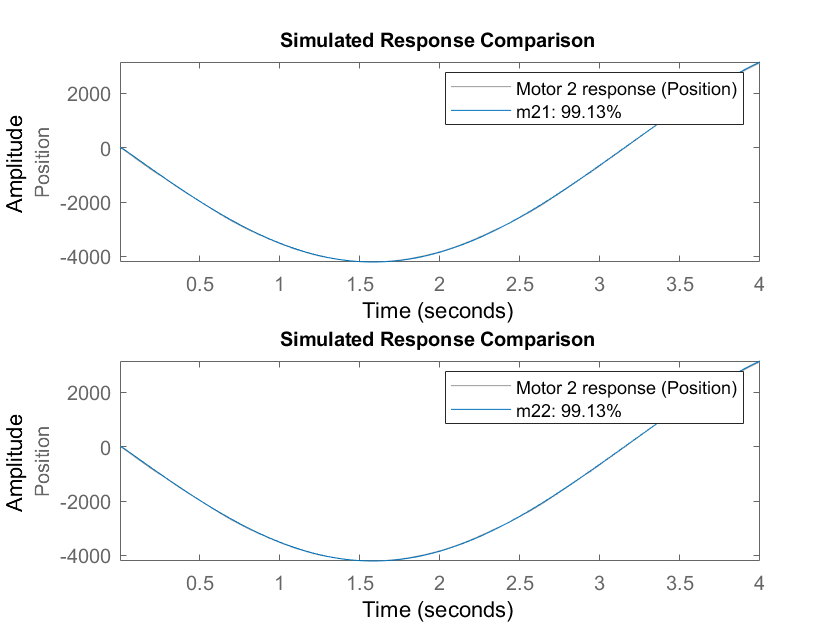

figure
subplot(2,1,1)
compare(data2,m21) % first order model evaluation
subplot(2,1,2)
compare(data2,m22) % second order model evaluation

From the results above, the first order transfer function model has competitive performance compared to second order variation. The first order transfer functions also reduce computation complexity. Thus it provides faster response.

clear m11 m21 data1 data2 opts tabularData
save Data/Exoskeleton/motorModel p1 p2 m12 m22 Ts
save Tests/Exp_MaxonMotors/expSetup sm_path sm_traj sm_t t_f
open('DoubleMotor_CSVposRef_ctrllerDesign.slx')